clear all; close all;

## Load data

load('Observation_nb.mat');                                         % load data
X =  y;                                          % 4-channel received signals
fs = fs;                                          % sample rate (Hz)

## Plot waveform

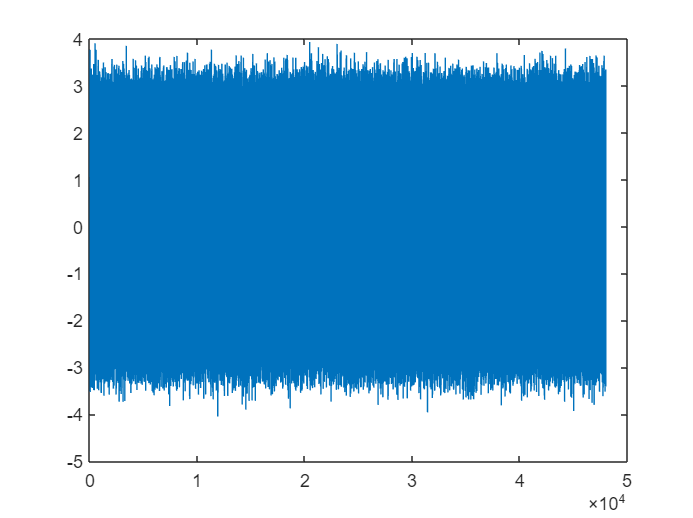

data = real(y(:,1));
figure;
plot(data);

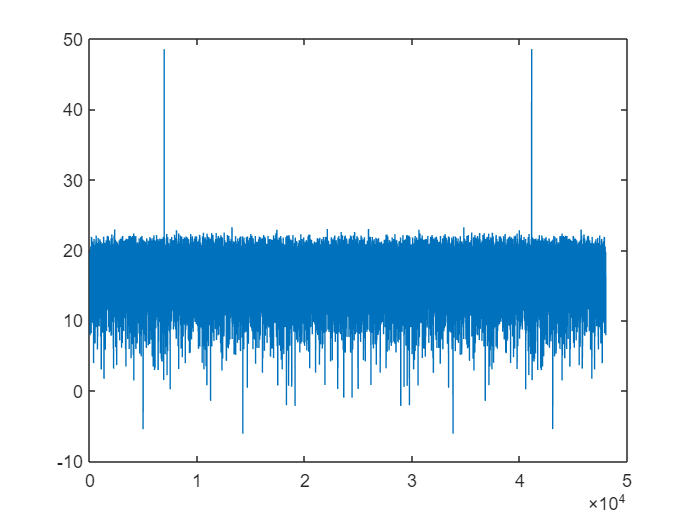

figure;
plot(10*log10(abs(fft(data))));

## Array setup

[Frame,nSensors] = size(X);
J = nSensors;                                      % number of sensors
dx = 0.034;                                            % inter-sensor distance in x direction (m)
dy = 0;                                             % sensor distance in y direction (m)
c = 340;                                           % sound velocity  (m)
n_source = 2;                                      % number of sources
Index = linspace(0,J-1,J);
p = (-(J-1)/2 + Index.') * [dx dy]                    % sensor position

p =    -0.0510         0
   -0.0170         0
    0.0170         0
    0.0510         0


## Plot sensor positions

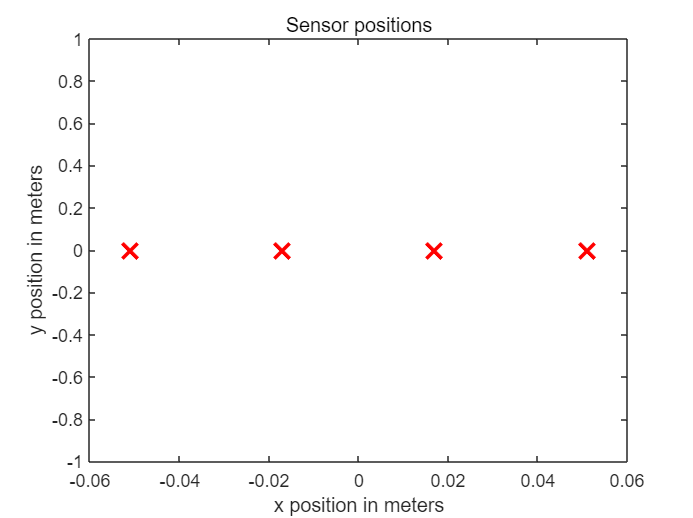

linspec = {'rx','MarkerSize',12,'LineWidth',2};
figure
plot(p(:,1),p(:,2),linspec{:});
title('Sensor positions');
xlabel('x position in meters');
ylabel('y position in meters');

disp('The four microphones are ready !');

The four microphones are ready !


## DoA estimation (MUSIC)

stride = 1;                                             % determine the angular resolution(deg)
theta = -90:stride:90;                                 % grid
f_c = 2300;                                                % center frequency  (Hz)
R_x = (X' * X) /fs;                                                % autocorrelation estimate
v =  [sin(theta*pi/180);-cos(theta*pi/180)]                    % direction vector

v =    -1.0000   -0.9998   -0.9994   -0.9986   -0.9976   -0.9962   -0.9945   -0.9925   -0.9903   -0.9877   -0.9848   -0.9816   -0.9781   -0.9744   -0.9703   -0.9659   -0.9613   -0.9563   -0.9511   -0.9455   -0.9397   -0.9336   -0.9272   -0.9205   -0.9135   -0.9063   -0.8988   -0.8910   -0.8829   -0.8746   -0.8660   -0.8572   -0.8480   -0.8387   -0.8290   -0.8192   -0.8090   -0.7986   -0.7880   -0.7771   -0.7660   -0.7547   -0.7431   -0.7314   -0.7193   -0.7071   -0.6947   -0.6820   -0.6691   -0.6561
   -0.0000   -0.0175   -0.0349   -0.0523   -0.0698   -0.0872   -0.1045   -0.1219   -0.1392   -0.1564   -0.1736   -0.1908   -0.2079   -0.2250   -0.2419   -0.2588   -0.2756   -0.2924   -0.3090   -0.3256   -0.3420   -0.3584   -0.3746   -0.3907   -0.4067   -0.4226   -0.4384   -0.4540   -0.4695   -0.4848   -0.5000   -0.5150   -0.5299   -0.5446   -0.5592   -0.5736   -0.5878   -0.6018   -0.6157   -0.6293   -0.6428   -0.6561   -0.6691   -0.6820   -0.6947   -0.7071   -0.7193   -0.7314   -0.7431   -0

d= p(:,1)'

d =    -0.0510   -0.0170    0.0170    0.0510


d = [d;d]

d =    -0.0510   -0.0170    0.0170    0.0510
   -0.0510   -0.0170    0.0170    0.0510


time_difference = d'*v./340;
a_theta = exp(-j*2*pi*time_difference*2300).';                 % steer vector

% implement eigen-decomposition and obtain the pseudo spectrum
[Ux, D] = eig(R_x);
EVA = diag(D)';
[EVA,I] = sort(EVA);
EVA = fliplr(EVA);
Ux = fliplr(Ux(:,I));

Un  = Ux(:,n_source+1:nSensors);                                                 % noise subspace (columns are eigenvectors), size: J*(J-n_source)
P_sm = 1./diag(a_theta*(Un*Un')*a_theta');          % pseudo music power

## Plot the MUSIC pseudo power spectrum

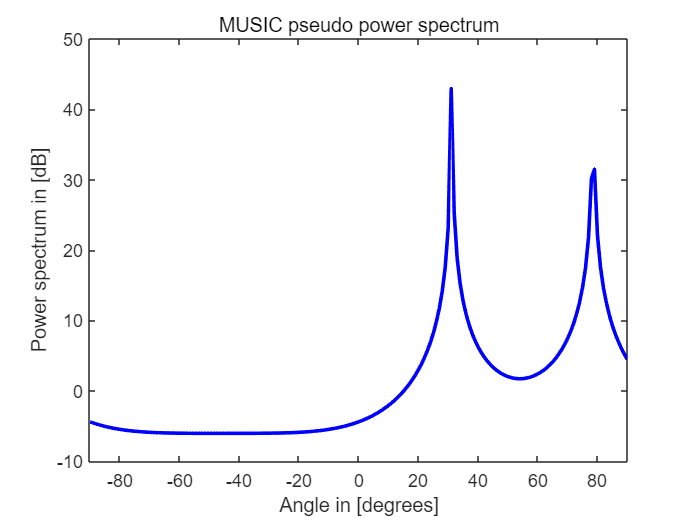

figure;
linspec = {'b-','LineWidth',2};
plot(theta, 10*log10(abs(P_sm)), linspec{:});
title('MUSIC pseudo power spectrum')
xlabel('Angle in [degrees]');
ylabel('Power spectrum in [dB]');
xlim([-90,90]);

## Find the local maximum and visualization

P_middle = abs(P_sm(2:end-1));
P_front = abs(P_sm(1:end-2));
P_back = abs(P_sm(3:end));
logic_front = (P_middle - P_front)>0;
logic_back = (P_middle - P_back)>0;
logic = logic_front & logic_back;
P_middle(~logic) = min(P_middle);
P_local = [abs(P_sm(1));P_middle;abs(P_sm(end))];
[~,doa_Idx] = maxk(P_local,n_source);
doa = theta(doa_Idx);
[~,minIdx] = min(abs(doa));
doa_source = doa(minIdx);
[~,maxIdx] = max(abs(doa));
interfer = doa(maxIdx);
disp(['The desired source DOA with MUSIC is: ',num2str(doa_source),' deg']);

The desired source DOA with MUSIC is: 31 deg


disp(['The interfering DOA with MUSIC is: ',num2str(interfer),' deg']);

The interfering DOA with MUSIC is: 79 deg
